## INTERPOLAZIONE POLINOMIALE

Sia $\Pi_n(x)\in\mathbb{P}_n$ il polinomio interpolante di grado n.

Sia $f:[a,b]\rightarrow\mathbb{R}$, dati $x_i\in[a,b]$ con $i=0,...,n$  $(x_i\neq x_j, \ i\neq j)$

**Condizione di interpolazione**: $\Pi_n(x_i)=f(x_i), \ \forall i=0,...,n$

Siano $\varphi_i(x)\subseteq \mathbb{P}_n$ $: \varphi_i(x_j)=\delta_{ij}=\begin{cases}1, \ i=j\\ 0, \ i\neq j\end{cases}$

e $\varphi_i(x)=\prod_{j=0, \ i\neq j}^n{\frac{x-x_j}{x_i-x_j}}$    (**polinomi caratteristici di Lagrange**).

Osserviamo che $\{\varphi_0(x),\varphi_1(x),...,\varphi_n(x)\}$ costituiscono una base per $\mathbb{P}_n$.

Dunque, ogni polinomio può essere scritto come combinazione lineare degli elementi della base.

In particolare, si dimostra che $\exists! \ \Pi_n(x)\in\mathbb{P}_n: \ \Pi_n(x_i)=f(x_i), \ \forall i=0,...,n$

ed è della forma: $\Pi_n(x)=\sum_{i=0}^nf(x_i)\varphi_i(x)$

Definiamo:

     
$$E_n(x)=f(x)-\Pi_n(x)=\frac{f^{(n+1)}(\xi(x))}{(n+1)!}\omega_{n+1}(x)$$


        con $\omega_{n+1}(x)=\prod_{i=0}^n(x-x_i)$ e $\xi(x)\in I$

per cui vale la seguente stima:

    
$$\|E_n(x)\|_\infty\leq\frac{\|f^{(n+1)}(x)\|_\infty}{(n+1)!}\omega_{(n+1)}(x)$$


**Nodi di interpolazione**: possono essere scelti in modo arbitrario, di seguito trattiamo alcuni casi notevoli:

    1) Nodi equispaziati

        Fissato l'intervallo $I=[a,b]$, prendiamo: $x_i=a+ih$ con $h=\frac{b-a}{n}$ e $i=0,...,n$

        In questo caso vale la stima: $\|\omega_{n+1}\|_\infty\leq\frac{1}{4}h^{n+1}n!$ , e di conseguenza: $\|E_n(x)\|_\infty\leq\frac{\|f^{(n+1)}(x)\|_\infty \ h^{n+1}}{4(n+1)}$

Usiamo l'esempio della funzione di Runge per mostrare che essa non può essere interpolata nell'intervallo $[-5,5]$, infatti le oscillazioni del polinomio interpolante divergono agli estremi dell'intervallo all'aumentare del numero di nodi di interpolazione.

f = @(x) 1 ./ (1 + x.^2); %funzione di Runge

xx = linspace(-5, 5, 1000);
X = linspace(-5, 5, 11); 
Y = f(X); %nodi di interpolazione

c = polyfit(X, Y, 10);

P = polyval(c, xx);

err = max(abs(f(xx) - P));

omega = polyval(poly(X), xx); 

    2) Nodi di Chebyshev-Gauss-Lobatto

         Scelgo $\hat{x}_i=-\cos{\left(\frac{\pi i}{n}\right)}$, con $i=0,...,n$ e $\hat{x}_i\in[-1,1]$

            e li proietto nell'intervallo $[a,b]$:  $x_i=\frac{a+b}{2}+\left(\frac{b-a}{2}\right)\hat{x}_i$

xCGL_ref = -cos(pi * [0: n] /n);

Unrecognized function or variable 'n'.


xCGL = xCGL_ref * (b - a) / 2 + (a + b) / 2;

    3) Nodi di Chebyshev-Gauss

         Scelgo $\hat{x}_i=-\cos{\left[\frac{(2i+1)\pi}{2n+1}\right]}$, con $i=0,...,n$ e $\hat{x}_i\in(-1,1)$

            e li proietto nell'intervallo $(a,b)$:  $x_i=\frac{a+b}{2}+\left(\frac{b-a}{2}\right)\hat{x}_i$

#### **Stabilità**

Consideriamo il polinomio $\tilde{\Pi}_n(x)$ che interpola i nodi perturbati $\tilde{f}(x_i)$.

Vale la seguente stima:

                                            
$$\|\tilde{\Pi}_n(x)-\Pi_n(x)\|_\infty\leq\Lambda_n \max_i{|f(x_i)-\tilde{f}(x_i)|}$$


                                       dove $\Lambda_n = \max_{x\in I}{\sum_{i=0}^n{|\varphi_i(x)|}}$   (costante di Lebesgue)

### Interpolazione composita

        
$$H=\frac{b-a}{k}$$


**Caso lineare**

            Vale la stima:

                    $\|\Pi_1^c(x)-f(x)\|_\infty\leq\frac{H^2}{8}\|f''(x)\|_\infty\rightarrow_{H\rightarrow 0}0$, $\forall f\in\mathcal{C}^2([a,b])$

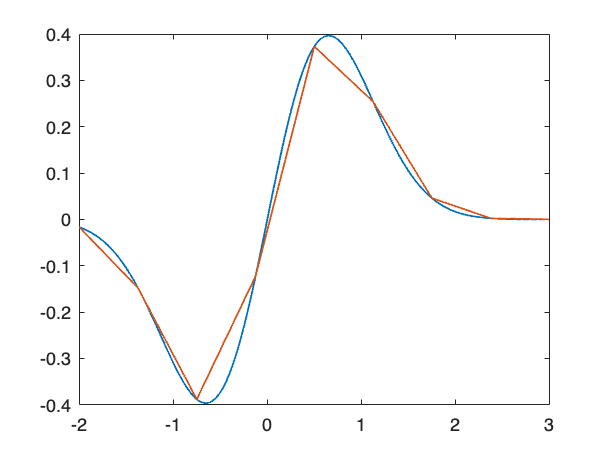

f = @(x) exp(-x.^2).*sin(x); % esempio interpolazione composita lineare
g = @(x) exp(-x.^2) .* (4*x.^2 .* sin(x)-4*x.*cos(x)-3*sin(x)); % derivata seconda di f(x)

a = -2;
b = 3;
n = 8;

xx = linspace(a,b,1000);

H = (b-a) / n;

X = a:H:b;
Y = f(X);

P = interp1(X,Y,xx);

plot(xx, f(xx), 'LineWidth',1)
hold on
plot(xx, P, 'LineWidth', 1)
hold off


epsilon = max(abs(f(xx)-P)); % errore
up = H^2 / 8 * max(abs(g(xx))); % stima errore


**Caso generale**

            Vale la stima:

                    $\|\Pi_k^c(x)-f(x)\|_\infty\leq\frac{H^{k+1}}{4(k+1)k^{k+1}}\|f^{(k+1)}(x)\|_\infty\rightarrow_{H\rightarrow 0}0$, $\forall f\in\mathcal{C}^{(k+1)}([a,b])$